**%%Homework 5**

Yuyu Fan

% Problem 1
% define the function
clear x;
f = inline('0.9*sin(x)-x', 'x');
x0=pi/4;
epsilon =10^-6;


%simple iterations
x(1) = x0;
gx= f(x(1))+x(1);
i=1;
while (abs(x(i) - gx)>epsilon)
    gx=x(i);
    x(i+1)=f(x(i))+x(i);
    i=i+1;
end
figure(1);
hold on
plot(x,'k-o')

%Newton-Raphson method
clear x;
df = inline('0.9*cos(x)-1','x')


df =

     Inline function:
     df(x) = 0.9*cos(x)-1



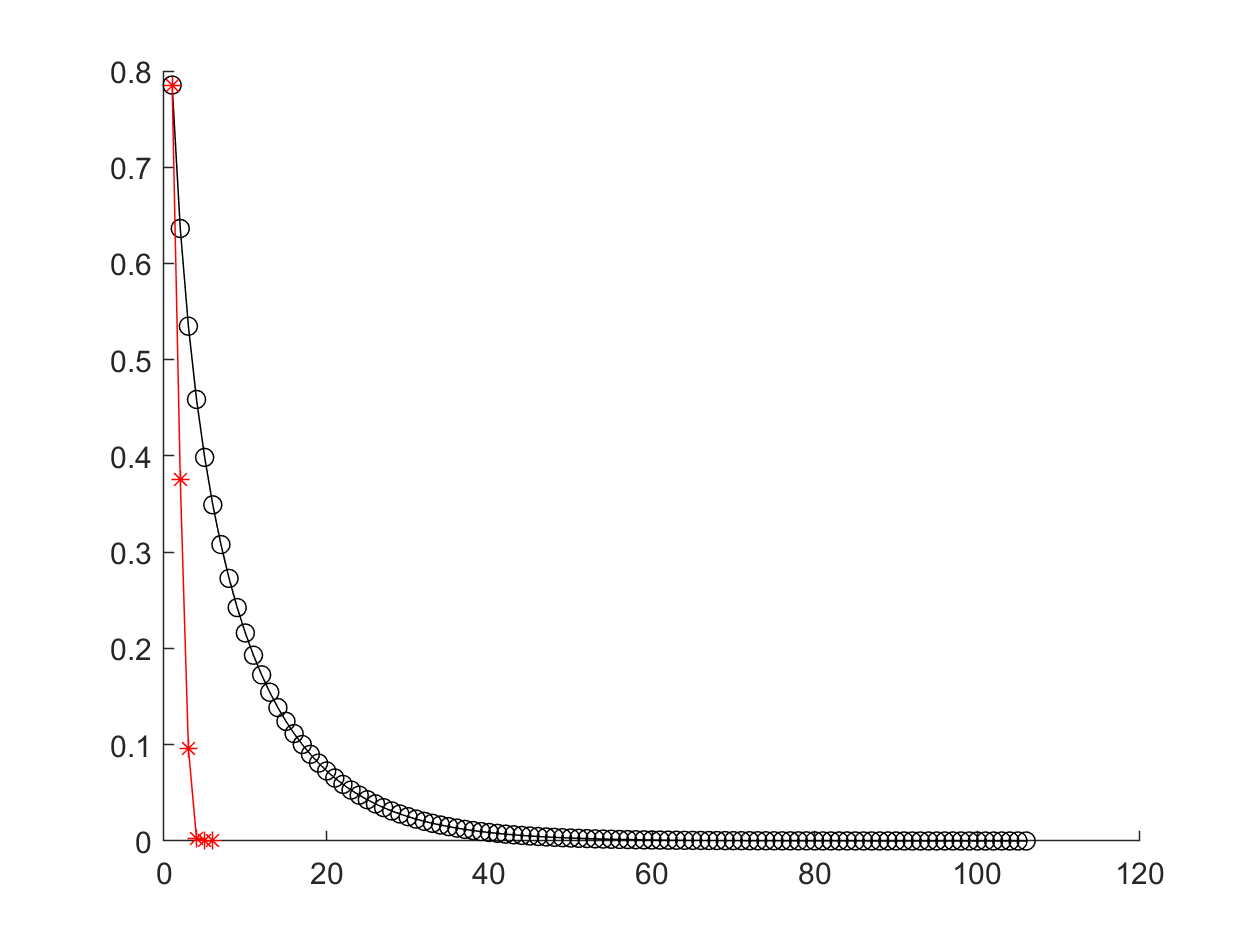

x(1)= x0;
gx = x(1) - f(x(1))/df(x(1));
i=1;
while (abs(x(i)-gx)>epsilon)
    gx=x(i);
    x(i+1)=x(i)-f(x(i))/df(x(i));
    i=i+1;
end
plot(x,'r-*')

%Problem 2
% define the function
clear x;
f = inline('x^5- 4.5*x^4 + 4.55*x^3 + 2.675*x^2 -3.3*x -1.4375','x');
x0=-0.6;
epsilon =10^-6;

%Newton-Raphson method
df= inline('5*x^4 - 18*x^3 + 13.65*x^2 + 5.35*x -3.3','x');
x(1)=x0;
gx = x(1)-f(x(1))/df(x(1));
i=1;
while (abs(x(i) - gx) >epsilon)
       gx= x(i);
       x(i+1)=x(i)-f(x(i))/df(x(i));
       i=i+1;
end
E = diff(x);
K= E(2:end) ./ E(1:end-1);
K(end)

ans = 0.5000

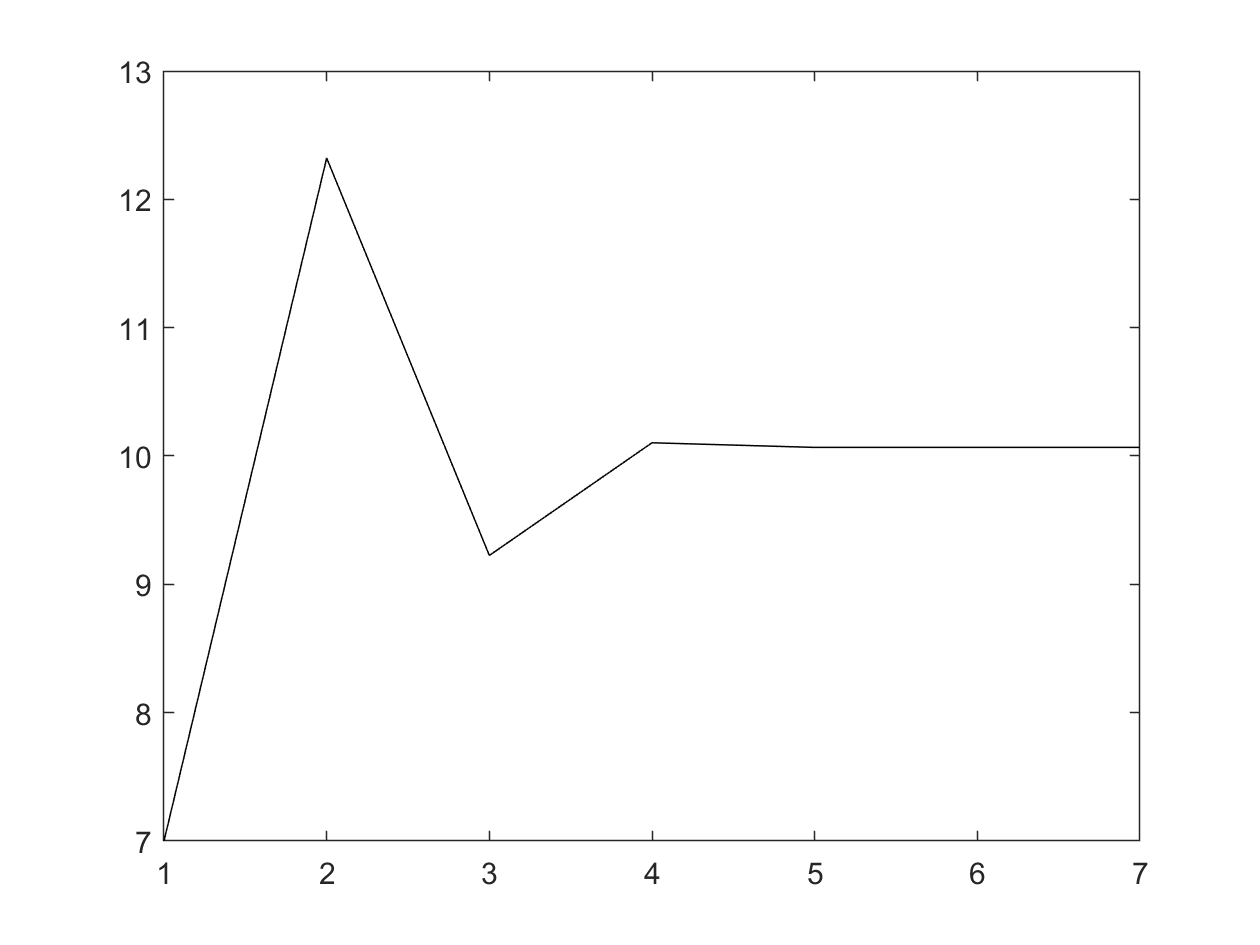

%Problem 3
clf;
load hw5_3_data
t0= 7;
epsilon =10^-6;

t(1)= t0;
dl = sum(1-2*exp(t(1)-X) ./ (1+ exp(t(1) - X)));
ddl = -2 * sum(exp(t(1) - X) ./ (1 + exp(t(1) - X)).^2);
gt = t(1) - dl/ ddl;
i =1;
while (abs(t(i) - gt) > epsilon)
    gt = t(i);
    dl = sum(1-2*exp(t(i)-X) ./ (1+ exp(t(i) - X)));
    ddl = -2 * sum(exp(t(i) - X) ./ (1 + exp(t(i) - X)).^2);
    t(i+1) = t(i)-dl/ddl;
    i=i+1;
end
plot(t, 'k');

t(end)

ans = 10.0670